## 初期化

clear;
clc;

## 対象のシステムを設定

model_name = "sample.slx";
target_system = "sample/Subsystem1";
%model_name = "bus_main_control_erga_soft_remove_goto_from_block.slx";
%target_system = "bus_main_control_erga_soft_remove_goto_from_block/plathome_input";

## モデル読み込み

open_system(model_name);

## サブシステムの接続先のサブシステムを取得

#### string配列の1番目に接続元のサブシステムを、2番目以降に接続先のサブシステム格納

#### string配列の要素が一つのときは、接続先のサブシステムがないことを表す

subsystem_list = find_system(target_system, 'SearchDepth', '1', 'BlockType', 'SubSystem');

% Compare To Constantブロックをsubsystem_listから除く
cnt = 0;
compare_to_constant =['Compare' newline 'To Constant'];
for i = 1:length(subsystem_list)
    if strfind(get_param(subsystem_list{i}, 'Name'), compare_to_constant)
        cnt = cnt+1;
    end
end

subsystem_relationship_list = cell(1, length(subsystem_list)-1-cnt);
index = 1;
for i = 1:length(subsystem_list)
    if strcmp(subsystem_list(i), target_system)
        continue;
    end
    
    subsystem_name = get_param(subsystem_list{i}, 'Name');
    if strfind(subsystem_name, compare_to_constant)
        continue;
    end
    
    subsystem_name = string(subsystem_name);
    input = subsystem_name;
    ph = get_param(subsystem_list{i}, 'PortHandles');
    for j = 1:length(ph.Outport)
        line = get_param(ph.Outport(j), 'Line');
        if line == -1
            continue
        end
        dst = get_param(line, 'DstBlockHandle');
        for k = 1:length(dst)
            dst_subsystemlist = get_source_subsystem_list(dst(k), input);
            input = dst_subsystemlist;    
        end
    end
    subsystem_relationship_list{index} = input;
    index = index + 1;
end

## モデルの依存関係を可視化する

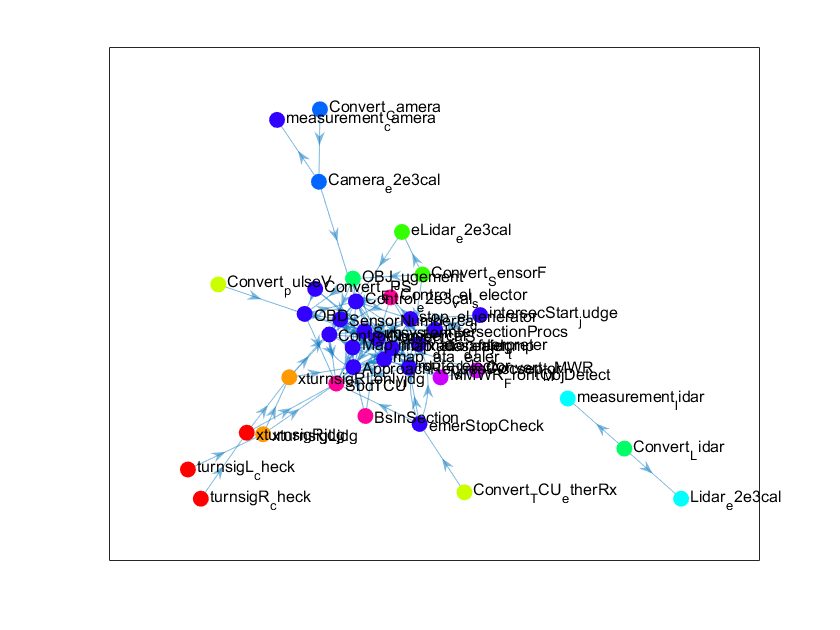

A = zeros(length(subsystem_relationship_list), length(subsystem_relationship_list));

names = cell(1, length(subsystem_relationship_list));
for i = 1:length(subsystem_relationship_list)
    names{i} = char(subsystem_relationship_list{i}(1));
end

for i = 1:length(subsystem_relationship_list)
    list = subsystem_relationship_list{i};
    if length(list) == 1
        continue;
    end
    for j = 1:length(names)
        if string(names{j}) == list(1)
            row = j;
            break;
        end
    end
    for j = 2:length(list)
        for k = 1:length(names)
            if string(names{k}) == list(j)
                A(row, k) = 1;
                break;
            end
        end
    end
end

G = digraph(A,names);
p = plot(G, 'Layout','force');

bins = conncomp(G);
p.MarkerSize = 7;
p.NodeCData = bins;
colormap(hsv(10))

function subsystem_list = get_source_subsystem_list(block, input_list)
    block_type = get_param(block, 'BlockType');
    %ブロックタイプを取得し、Subsystemの場合はsubsystem_listにサブシステム名を追加し、returnする
    if strcmp(block_type, "SubSystem")
        subsystem_name = string(get_param(block, 'Name'));
        f = true;
        for i = 1:length(input_list)
            if strcmp(subsystem_name, input_list(i))
                f = false;
                break;
            end
        end
        if f == true
            subsystem_list = [input_list, subsystem_name];
        else
            subsystem_list = input_list;
        end
        return
    %ブロックタイプがOutport、UnitDelay、Delay、Gotoの時は、input_listをreturnする
    elseif strcmp(block_type, "Outport")   ||...
           strcmp(block_type, "UnitDelay") ||...
           strcmp(block_type, "Delay")     ||...
           strcmp(block_type, "Goto")
        subsystem_list = input_list;
        return
    end
    
    %blockの接続先のブロックを取得し、再帰的に処理
    ph = get_param(block, 'PortHandles');
    for i = 1:length(ph.Outport)
        line = get_param(ph.Outport(i), 'Line');
        if line == -1
            continue;
        end
        dst = get_param(line, 'DstBlockHandle');
        for j = 1:length(dst)
            res = get_source_subsystem_list(dst(j), input_list);
            input_list = res;
        end
    end
    subsystem_list = input_list;
end